clear all
format shortg

# Prosjektoppgaver

## Oppgave 1

### a) Eksponent funksjonen

*Implementer eksponentfunksjonen i likning *(21)*. Input skal være en matrise på formen *(18)*. Funksjonen bør ta inn både *h *og *Ω *som input. Lag et testprogram som sjekker om output *X *er en matrise som oppfyller kravet *$X^T X={\textrm{Id}}_{\textrm{3x3}}$*. *				

Oppretter testdata 

h = 0.0001;
omega = rotating_matrix([1, 6, 5]);
X = exponent_function(h, omega);

Sjekker om $X^T X={\textrm{Id}}_{\textrm{3x3}}$

X' * X

ans =             1   1.9002e-07   3.0999e-07
   1.9002e-07            1  -2.9001e-07
   3.0999e-07  -2.9001e-07            1


### b) Kinetisk energi

*Implementer en funksjon som regner ut energien til et roterende legeme som har treg- hetsmoment *I *og rotasjonsvektor *ω*. Denne vil dere trenge til å sjekke om simuleringene bevarer energien til T-nøkkelen. *			

I = [[2 0 0];
	 [0 3 0];
	 [0 0 1]];
w =  [1 1 -1]';
K = kinetic_energy(I, w) % Joule

K =      3


### c) Treghetsmoment

*Regn ut treghetsmomentet til T-nøkkelen ved å bruke formelen i forige avsnitt. *						

Vi har følgende mål for T-Nøkkelen:

Håndtaket:

L_handle = 8.0; % cm
R_handle = 1.0; % cm
center_handle = [-1 0 0]; 
init_Handle = [R_handle, L_handle, center_handle];

Skaftet:

L_shaft = 4.0; % cm
R_shaft = 1.0; % cm
center_shaft = [2 0 0]; 
init_Shaft  = [R_shaft, L_shaft, center_shaft];

Tettheten til materialet T-nøkkelen er laget av er:

p = 6.7; % gram/cm^3

og massesenteret samt den totale massen for T-nøkkelen er:

center_body = [0 0 0]; 
mass_Body   = 12 * pi * p;

Regner ut Treghetsmomentet til T-nøkkelen

I_THandle = moment_of_inertia(R_handle, L_handle, R_shaft, L_shaft, p)

I_THandle =        982.27            0            0
            0       722.67            0
            0            0       1578.7


Visualiserer T-nøkkelen

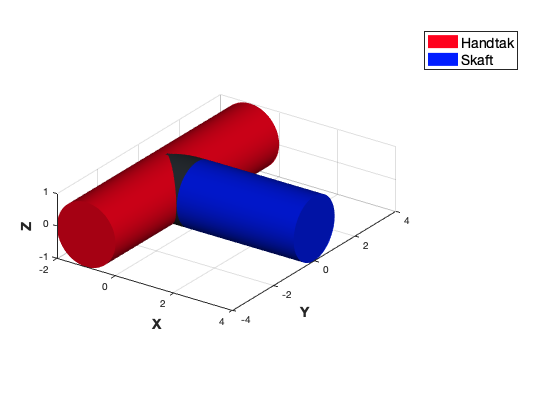

draw_T_handle(init_Handle, init_Shaft)

## Oppgave 2

*Gitt spesialtilfellet der legemet er en kule. Dere kan da anta at treghetsmomentet er lik identitetsmatrisen. La også startbetingeslen til *X(t) *være lik identitetsmatrisen. La *L = [1, 0, 0]*. Løs likningene *(19) *og *(20) *eksakt.*

X = eye(3);
I_sphere = eye(3);
L = [1 0 0]';

w = angular_velocity(X, I_sphere, L)

w =      1
     0
     0


dX = derivative_of_X(X, rotating_matrix(w))

dX =      0     0     0
     0     0    -1
     0     1     0


Den eksakte løsningen for $X\left(t\right)$ er:


$$X\left(t\right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(t\right) & -\sin \left(t\right)\\
0 & \sin \left(t\right) & \cos \left(t\right)
\end{array}\right\rbrack$$


X_exact = @(t)[[1      0       0];
	           [0 cos(t) -sin(t)];
	           [0 sin(t) cos(t)]];  

## Oppgave 3				

*Implementer varianten av Eulers metode gitt i likning *(25) *i avnsitt 4.1. Og test *				

*metoden på systemet som består av likningene *(19) *og *(20)*. *

Sammenligner eulersmetode med den eksakte løsningen for kulen:

X_euler = euler_method([0 1], X, h, I_sphere, L)

X_euler =             1            0            0
            0      0.54033     -0.84147
            0      0.84156      0.54033


X_exact(1) - X_euler

ans =             0            0            0
            0  -2.7021e-05  -3.3772e-09
            0  -8.4148e-05  -2.7021e-05


## Oppgave 4			

*Implementer varianten av RK4-metoden beskrevet i avsnitt 4.4. Dere kan om dere vil implementere varianten av Runge Kutta Fehlberg-metoden (RKF45) som er beskrevet i avsnitt 4.5. Vær nøye på å implementere metoden nøyaktig slik den står. En liten feil i koefisientene vil gjøre metoden omtrent like unøaktig som Eulers metode. *

Sammenligner RK4 med den eksakte løsningen for kulen for å verifisere at den gir korrekt resultat:

[X_RK4, A_all] = RK4([0 1], X, h, I_sphere, L);
X_RK4

X_RK4 =             1            0            0
            0      0.54033     -0.84147
            0      0.84156      0.54033


X_exact(1) - X_RK4

ans =             0            0            0
            0  -2.7021e-05  -3.3772e-09
            0  -8.4148e-05  -2.7021e-05


## Oppgave 5 og 6		

*Bruk implementeringen av RK4 eller RKF45 til å løse systemet. Benytt treghets- momentet til T-nøkkelen som ble utregnet i tidligere oppgave. Bruk *$X\left(0\right)={\textrm{Id}}_{3\textrm{x3}}$*. Beregn *L *slik at *ω(0) *har lengde ca lik 1 ved tiden 0. *

*Tegn opp komponentene til løsningene *X* som ni funksjoner av tiden. Gi en tolkning av disse grafene. Alternativt kan dere lage en 3-D animasjon av T-nøkkelen som roterer. *

time_interval = [0 100]; % sekunder
X = eye(3); % Startposisjon

### a) $\omega^{\to } \left(0\right)={\left\lbrack 1,0\ldotp 05,0\right\rbrack }^T$

w = [1 0.05 0]';
La = torque(X, I_THandle, w);

Solving the equations with the RK4 method:

[Xa, Xa_all] = RK4(time_interval, X, h, I_THandle, La);

Plotting results

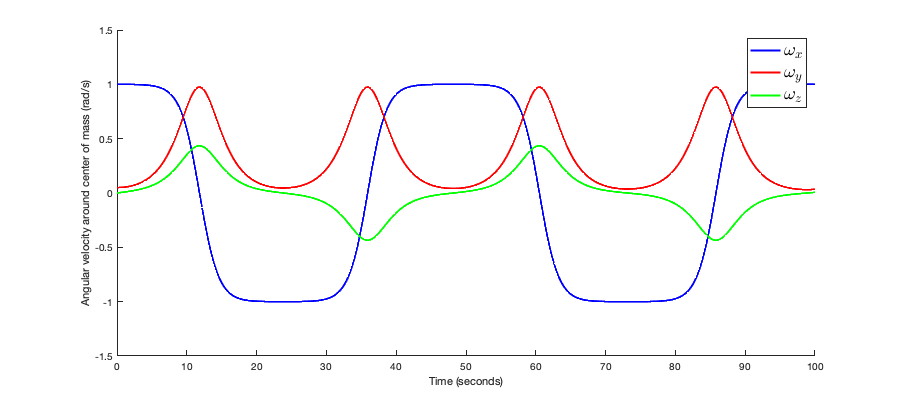

plot_AngularVelocity(Xa_all, time_interval, I_THandle, La);

### b) $\omega^{\to } \left(0\right)={\left\lbrack 0,\;1,\;0\ldotp 05\right\rbrack }^T$

w = [0 1 0.05]';
Lb = torque(X, I_THandle, w);

[Xb, Xb_all] = RK4(time_interval, X, h, I_THandle, Lb);

Plotting results

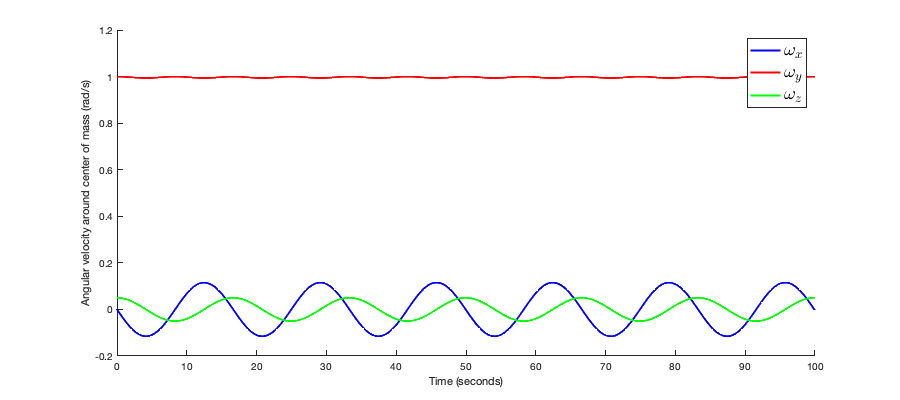

plot_AngularVelocity(Xb_all, time_interval, I_THandle, Lb);

### c) $\omega^{\to } \left(0\right)={\left\lbrack 0\ldotp 05,\;0,1\right\rbrack }^T$

w = [0.05 0 1]';
Lc = torque(X, I_THandle, w);

[Xc, Xc_all] = RK4(time_interval, X, h, I_THandle, Lc);

Plotting results

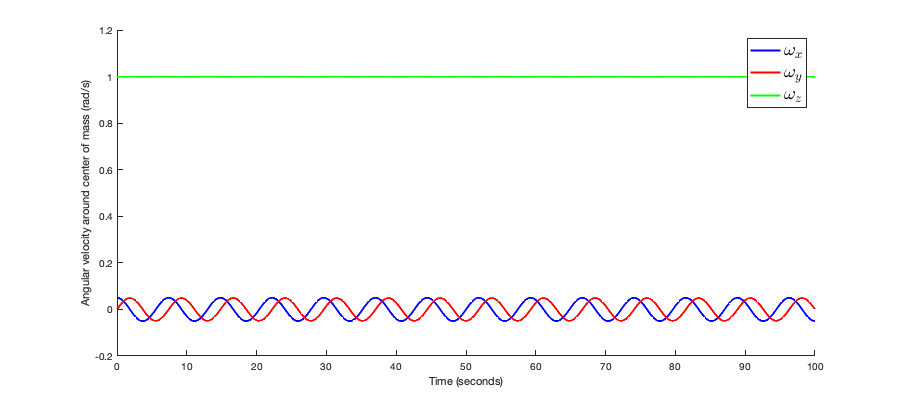

plot_AngularVelocity(Xc_all, time_interval, I_THandle, Lc);

### Plotting the total kinetic energy for the different initial values

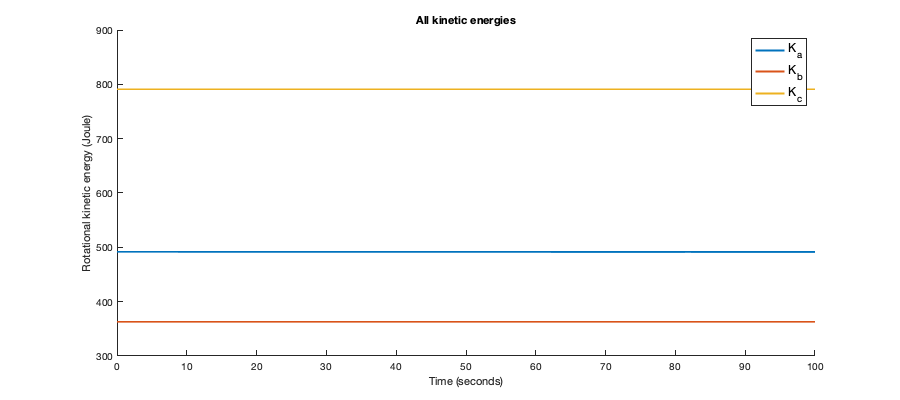

plot_KineticEnergy_all(Xa_all, Xb_all, Xc_all, La, Lb, Lc, I_THandle, time_interval);